%% Setup
N      = 2048;
window = 10;
t      = linspace(-window/2, window/2, N);
T      = t(end) - t(1);
dt     = T / N;

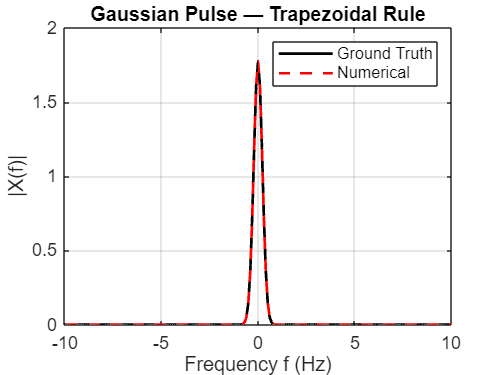

%% 1. Gaussian Pulse
xt_gauss = exp(-t.^2);

[f_tr, X_tr]   = ftr(t, xt_gauss, T, 'trapz');
[f_fft, X_fft] = ftr(t, xt_gauss, T);

[tg_tr, xg_tr]   = iftr(f_tr,  X_tr, 2*pi*f_tr,  'trapz');
[tg_fft, xg_fft] = iftr(f_fft, X_fft, 2*pi*f_fft);

% Analytic FT
X_true = sqrt(pi) * exp(-pi^2 * f_tr.^2);

% Forward plots
figure('Name','Gaussian CTFT – trapz');
plot(f_tr, abs(X_true), 'k-', 'LineWidth', 1.5), hold on
plot(f_tr, abs(X_tr), 'r--', 'LineWidth', 1.5), grid on
xlabel('Frequency f (Hz)'), ylabel('|X(f)|')
title('Gaussian Pulse — Trapezoidal Rule')
legend('Ground Truth', 'Numerical')
xlim([-10 10])

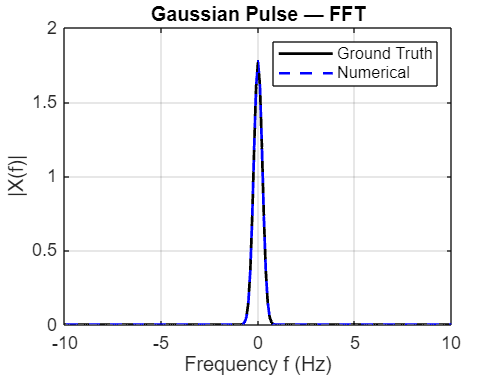


figure('Name','Gaussian CTFT – FFT');
plot(f_fft, X_true, 'k-', 'LineWidth', 1.5), hold on
plot(f_fft, abs(X_fft), 'b--', 'LineWidth', 1.5), grid on
xlabel('Frequency f (Hz)'), ylabel('|X(f)|')
title('Gaussian Pulse — FFT')
legend('Ground Truth', 'Numerical')
xlim([-10 10])

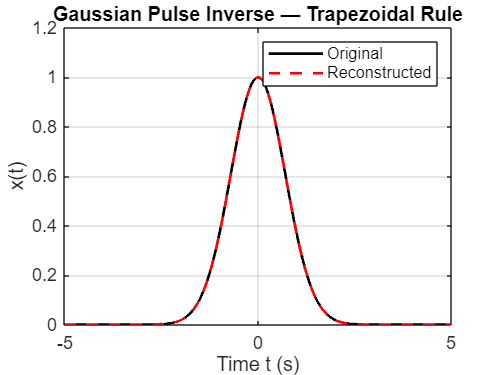


% Inverse plots
figure('Name','Gaussian inverse – trapz');
plot(t, xt_gauss, 'k-', 'LineWidth', 1.5), hold on
plot(tg_tr, real(xg_tr), 'r--', 'LineWidth', 1.5), grid on
xlabel('Time t (s)'), ylabel('x(t)')
legend('Original', 'Reconstructed')
title('Gaussian Pulse Inverse — Trapezoidal Rule')
xlim([-5 5])

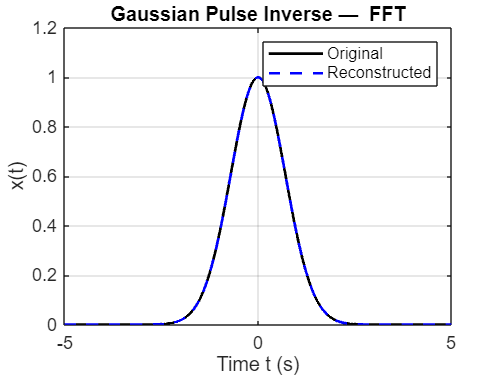


figure('Name','Gaussian inverse – IFFT');
plot(t, xt_gauss, 'k-', 'LineWidth', 1.5), hold on
plot(tg_fft, real(xg_fft), 'b--', 'LineWidth', 1.5), grid on
xlabel('Time t (s)'), ylabel('x(t)')
legend('Original', 'Reconstructed')
title('Gaussian Pulse Inverse —  FFT')
xlim([-5 5])

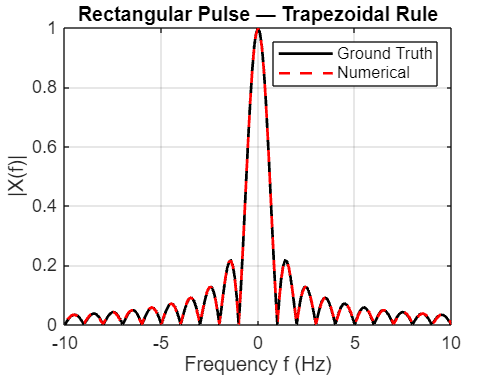

%% 2. Rectangular Pulse
xt_rect = double(abs(t) <= 0.5);

[f_tr, X_tr]   = ftr(t, xt_rect, T, 'trapz');
[f_fft, X_fft] = ftr(t, xt_rect, T);

[tr_tr, xr_tr]   = iftr(f_tr,  X_tr, 2*pi*f_tr,  'trapz');
[tr_fft, xr_fft] = iftr(f_fft, X_fft, 2*pi*f_fft);

% Analytic FT: sinc(f)
X_true = sinc(f_tr);

figure('Name','Rectangular CTFT – trapz');
plot(f_tr, abs(X_true), 'k-', 'LineWidth', 1.5), hold on
plot(f_tr, abs(X_tr), 'r--', 'LineWidth', 1.5), grid on
xlabel('Frequency f (Hz)'), ylabel('|X(f)|')
title('Rectangular Pulse — Trapezoidal Rule')
legend('Ground Truth', 'Numerical')
xlim([-10 10])

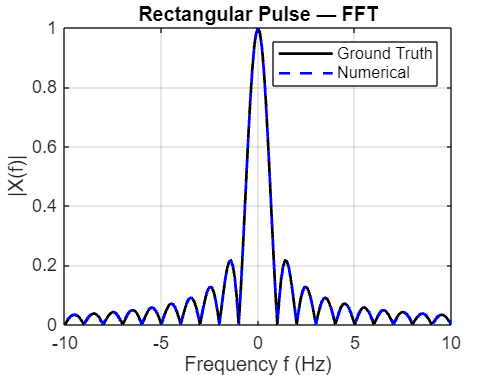


figure('Name','Rectangular CTFT – FFT');
plot(f_fft, abs(X_true), 'k-', 'LineWidth', 1.5), hold on
plot(f_fft, abs(X_fft), 'b--', 'LineWidth', 1.5), grid on
xlabel('Frequency f (Hz)'), ylabel('|X(f)|')
title('Rectangular Pulse — FFT')
legend('Ground Truth', 'Numerical')
xlim([-10 10])

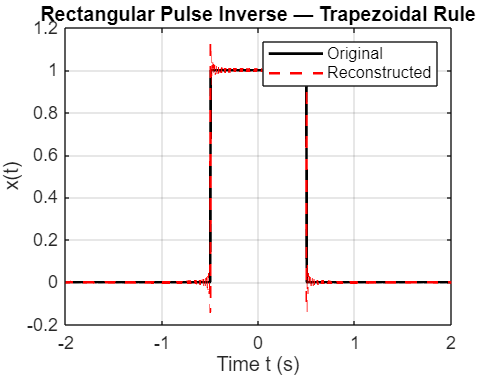


figure('Name','Rectangular inverse – trapz');
plot(t, xt_rect, 'k-', 'LineWidth', 1.5), hold on
plot(tr_tr, real(xr_tr), 'r--', 'LineWidth', 1.5), grid on
xlabel('Time t (s)'), ylabel('x(t)')
legend('Original', 'Reconstructed')
title('Rectangular Pulse Inverse — Trapezoidal Rule')
xlim([-2 2])

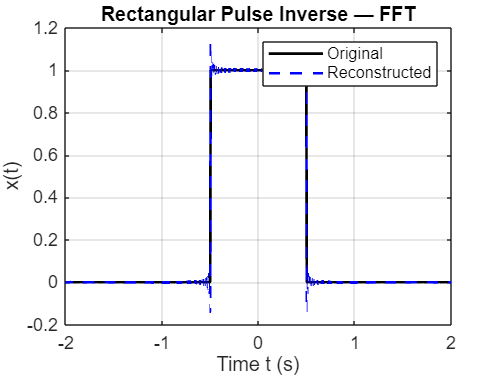


figure('Name','Rectangular inverse – IFFT');
plot(t, xt_rect, 'k-', 'LineWidth', 1.5), hold on
plot(tr_fft, real(xr_fft), 'b--', 'LineWidth', 1.5), grid on
xlabel('Time t (s)'), ylabel('x(t)')
legend('Original', 'Reconstructed')
title('Rectangular Pulse Inverse — FFT')
xlim([-2 2])

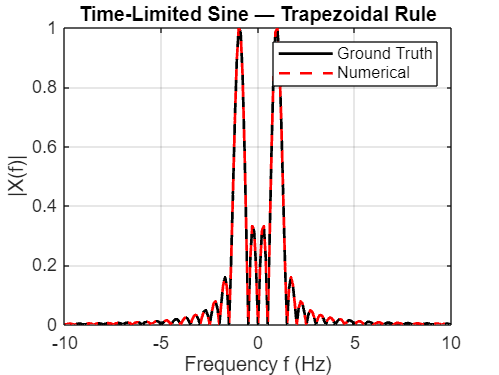

%% 3. Time-Limited Sine
xt_sine = sin(2*pi*t) .* (abs(t) < 1);

[f_tr, X_tr]   = ftr(t, xt_sine, T, 'trapz');
[f_fft, X_fft] = ftr(t, xt_sine, T);

[ts_tr, xs_tr]   = iftr(f_tr,  X_tr, 2*pi*f_tr,  'trapz');
[ts_fft, xs_fft] = iftr(f_fft, X_fft, 2*pi*f_fft);

% Define the Fourier Transform expression
X_true = (1j).^(-1) .* (sinc(2*(f_tr - 1)) - sinc(2*(f_tr + 1)));

figure('Name','Sine CTFT – trapz');
plot(f_tr, abs(X_true), 'k-', 'LineWidth', 1.5), hold on
plot(f_tr, abs(X_tr), 'r--', 'LineWidth', 1.5), grid on
xlabel('Frequency f (Hz)'), ylabel('|X(f)|')
title('Time-Limited Sine — Trapezoidal Rule')
legend('Ground Truth', 'Numerical')
xlim([-10 10])

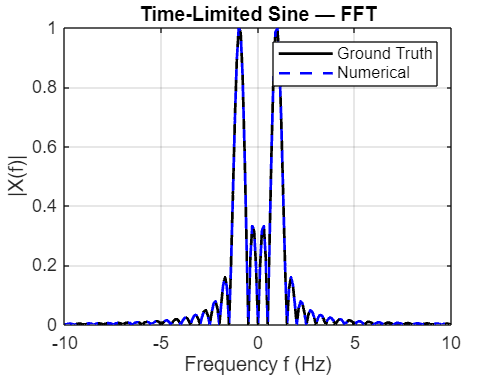


figure('Name','Sine CTFT – FFT');
plot(f_fft, abs(X_true), 'k-', 'LineWidth', 1.5), hold on
plot(f_fft, abs(X_fft), 'b--', 'LineWidth', 1.5), grid on
xlabel('Frequency f (Hz)'), ylabel('|X(f)|')
title('Time-Limited Sine — FFT')
legend('Ground Truth', 'Numerical')
xlim([-10 10])

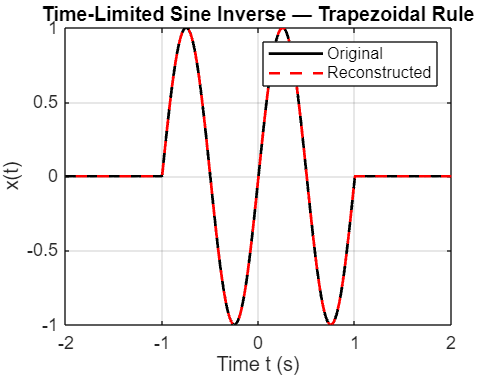


figure('Name','Sine inverse – trapz');
plot(t, xt_sine, 'k-', 'LineWidth', 1.5), hold on
plot(ts_tr, real(xs_tr), 'r--', 'LineWidth', 1.5), grid on
xlabel('Time t (s)'), ylabel('x(t)')
legend('Original', 'Reconstructed')
title('Time-Limited Sine Inverse — Trapezoidal Rule')
xlim([-2 2])

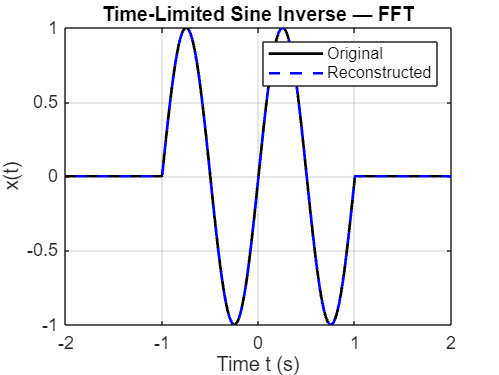


figure('Name','Sine inverse – IFFT');
plot(t, xt_sine, 'k-', 'LineWidth', 1.5), hold on
plot(ts_fft, real(xs_fft), 'b--', 'LineWidth', 1.5), grid on
xlabel('Time t (s)'), ylabel('x(t)')
legend('Original', 'Reconstructed')
title('Time-Limited Sine Inverse — FFT')
xlim([-2 2])